Exercise 3.3

%Load data from file
X=load('ChlorellaGrowth.txt');

%Define vectors by slicing data. i.e. Extracting data.
subplot(2,1,1)
Light=X(:,1); rmax=X(:,2); 

%Repeat computations from Intro1
C1=polyfit(Light,rmax,1)

C1 =     0.0136    1.5810


xvals=0:120; 
yhat1=polyval(C1,xvals);

subplot(2,1,1)
C1=polyfit(log(Light),log(rmax),1)

C1 =     0.2646   -0.1940


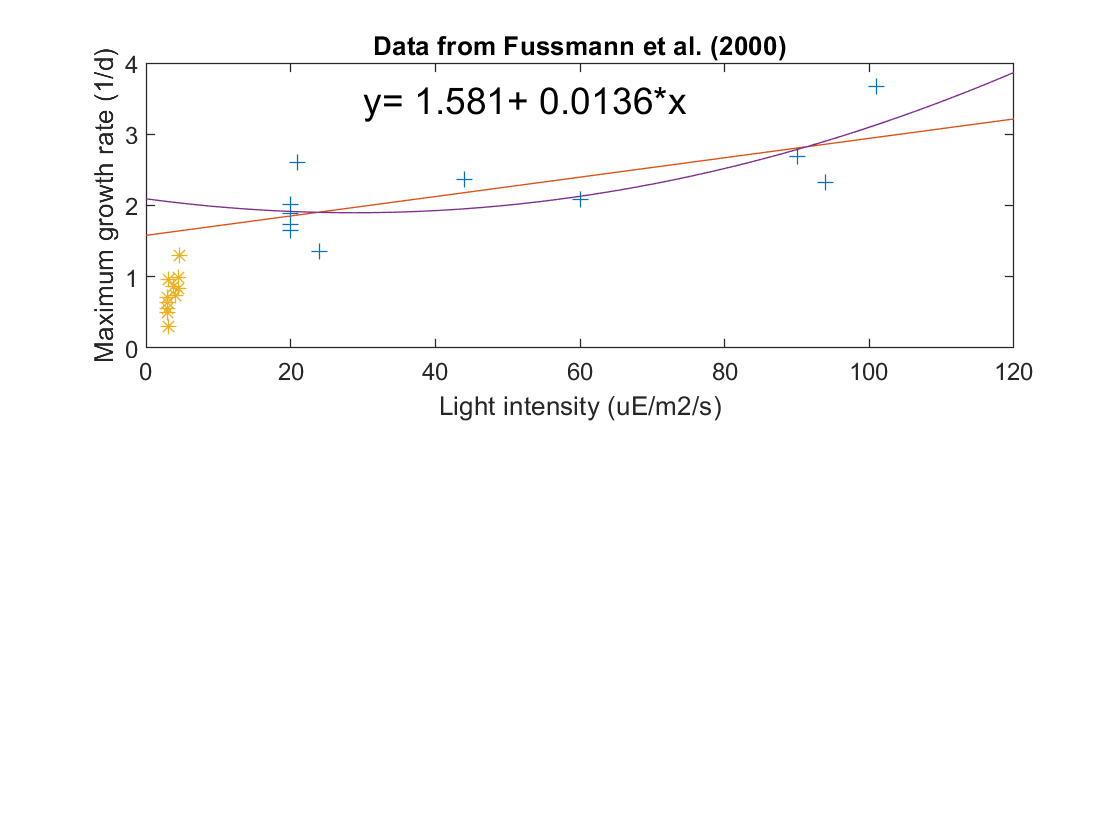

yhat2=polyval(C2,xvals);

plot(Light,rmax,'+',xvals,yhat1, log(Light),log(rmax),'*',xvals,yhat2);
%Annotate plot with labels, title and text
xlabel('Light intensity (uE/m2/s)','Fontsize',14); 
ylabel('Maximum growth rate (1/d)','Fontsize',14);
title('Data from Fussmann et al. (2000)','FontSize',14);
text(30,3.5,'y= 1.581+ 0.0136*x','Fontsize',14);